# ΕΡΓΑΣΙΑ 2 - ΚΩΔΙΚΑΣ

## ΕΡΩΤΗΜΑ 3

%{
m = 4;


% Random values for the main diagonal
main_diag = randi(10, 1, m);    

% Random values for the first upper diagonal
upper_diag = randi(10, 1, m-1); 

% Create the upper bidiagonal matrix B
B = diag(main_diag) + diag(upper_diag, 1)

% Create the matrix A 
A = [zeros(m), B; B', zeros(m)];

% Display the final square matrix A
disp('The matrix A is:')
disp(A);

n = size(A,1); % size of A

% Create the identity matrix I
I = eye(n); 

% Define the row permutation of I
r = 3;      % You can change this value to experiment
% r=4;
% r=5;
perm = [];
for i = 1:r
    indices = i:r:n;
    perm = [perm, indices];
end

% Row permutation of I
P = I(perm, :)

T = P * A * P'
D = T'

% I notice that for different values of r, 
% the matrix T remains SYMMETRIC !!!

## ΕΡΩΤΗΜΑΤΑ 8α) και 8β)

% Ορισμός των n
n_values = 2.^(6:12);    % n = [64, 128, 256, 512, 1024, 2048, 4096]

% Δοκιμή για κάθε n
for i = 1:length(n_values)
    n = n_values(i); % Τρέχουσα τιμή του n

    % Δημιουργία τυχαίων διανυσμάτων και μήτρας
    x = rand(n, 1);
    y = rand(n, 1);
    I = eye(n);
    B = rand(2*n, m);

    % Δημιουργία της μήτρας A
    A = HamIbuild(x, y);

    % Ορισμός της συνάρτησης πολλαπλασιασμού για timeit
    multiplyFunc = @() mtimes(A, B);

    % Χρονομέτρηση της εκτέλεσης του πολλαπλασιασμού
    elapsedTime = timeit(multiplyFunc);

    % Εμφάνιση των αποτελεσμάτων
    fprintf('n = %d, Elapsed time for multiplication: %.6f seconds\n', n, elapsedTime);
end

## ΕΡΩΤΗΜΑ 8γ)

% Ορισμός των n
n_values = 2.^(6:12);    % n = [64, 128, 256, 512, 1024, 2048, 4096]
s = 3; % ή οποιοδήποτε μικρό αριθμό για s

% Δοκιμή για κάθε n
for i = 1:length(n_values)
    n = n_values(i); % Τρέχουσα τιμή του n

    % Δημιουργία τυχαίων διανυσμάτων και μήτρας
    x = rand(n, 1);
    y = rand(n, 1);
    B = rand(2*n, s); % Μητρώο 2n x s

    % Χρονομέτρηση της εκτέλεσης της HAMM
    hammFunc = @() HAMM(x, y, B);
    elapsedTimeHAMM = timeit(hammFunc);

    % Εμφάνιση των αποτελεσμάτων
    fprintf('n = %d, Elapsed time for HAMM multiplication: %.6f seconds\n', n, elapsedTimeHAMM);
end
%}

## ΕΡΩΤΗΜΑ 9β)

n1 = randi(10);
n2 = randi(10);
n3 = randi(10);
m1 = randi(10);
m2 = randi(10);
m3 = randi(10);

A1 = rand(n1,m1);
A2 = rand(n2,m2);
A3 = rand(n3,m3);

x = rand(m1*m2*m3,1);


% 1ος τρόπος
A_temp = kron(A1,A2);
A_final = kron(A_temp, A3);
R = A_final * x

R =     4.2308
    6.6305
    6.4367
    7.0741
    4.1912
    6.3992
    6.2555
    6.9137
    5.0453
    7.5748



% 2ος τρόπος



## ΕΡΩΤΗΜΑ 10

% Define a range of matrix sizes to test
sizes = 2.^(1:9); 
nmin = 64;           % Minimum size for Strassen's algorithm

% Arrays to store execution times
strassen_times = zeros(size(sizes));
winograd_times = zeros(size(sizes));

% Loop through each size and measure performance
for i = 1:length(sizes)
    n = sizes(i); 
    
    A = rand(n);
    B = rand(n);
     
    strassen_time = @(A, B) strass(A, B, n, nmin);
    winograd_time = @(A, B) winograd(A, B);
    
    % Measure the performance of Strassen's algorithm
    strassen_times(i) = timeit(@() strassen_time(A, B));
    
    % Measure the performance of Winograd's algorithm
    winograd_times(i) = timeit(@() winograd_time(A, B));
end

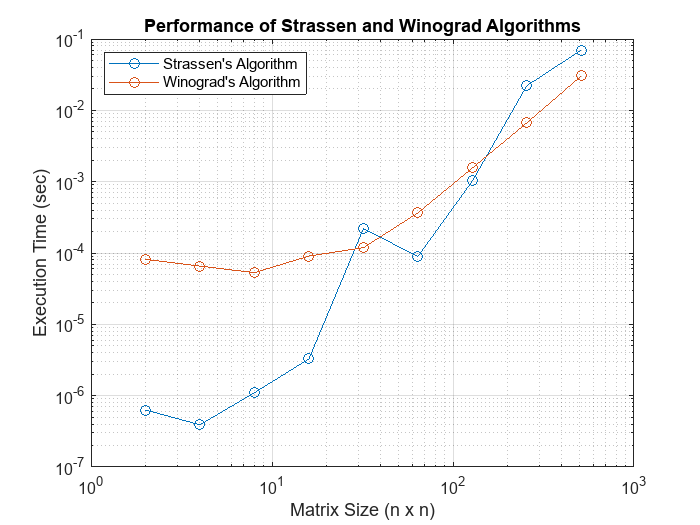


% Plot the results
figure;
loglog(sizes, strassen_times, '-o', 'DisplayName', 'Strassen''s Algorithm');
hold on;
loglog(sizes, winograd_times, '-o', 'DisplayName', 'Winograd''s Algorithm');
hold off;


xlabel('Matrix Size (n x n)');
ylabel('Execution Time (sec)');
title('Performance of Strassen and Winograd Algorithms');
legend('Location', 'northwest');
grid on;

## Παρατήρηση με βάση το γράφημα: 

## Αφού έτρεξα τον παραπάνω κώδικα του Ερωτήματος 10 κάμποσες φορές, διαπίστωσα από το γράφημα ότι για n μεγαλύτερο από περίπου 2^7 παρατηρώ καλύτερη απόδοση για τον αλγόριθμο Winograd συγκριτικά με τον Strassen  (αναμενόμενο).

## %% Συναρτήσεις Ερωτημάτων

## Συναρτήσεις Ερωτήματος 10

function C = strass(A, B, n, nmin)
   
    % Ελέγχουμε αν το μέγεθος της μήτρας είναι μικρότερο ή ίσο με το ελάχιστο μέγεθος
    if n <= nmin
        % Αν n <= nmin, υπολογίζουμε το C = AB με συμβατικό πολλαπλασιασμό
        C = A * B; 
    else
        % Διαχωρίζουμε τα μητρώα A και B σε υπομητρώα
        m = n / 2;      % Το μέγεθος των υπομητρώων
        u = 1:m;        % Οι γραμμές και στήλες του πρώτου υπομητρώου
        v = m + 1:n;    % Οι γραμμές και στήλες του δεύτερου υπομητρώου
        
        % Υπολογίζουμε τα P1 έως P7 με αναδρομή
        P1 = strass(A(u, u) + A(v, v), B(u, u) + B(v, v), m, nmin);
        P2 = strass(A(v, u) + A(v, v), B(u, u), m, nmin);
        P3 = strass(A(u, u), B(u, v) - B(v, v), m, nmin);
        P4 = strass(A(v, v), B(v, u) - B(u, u), m, nmin);
        P5 = strass(A(u, u) + A(u, v), B(v, v), m, nmin);
        P6 = strass(A(v, u) - A(u, u), B(u, u) + B(u, v), m, nmin);
        P7 = strass(A(u, v) - A(v, v), B(v, u) + B(v, v), m, nmin);
        
        % Συνδυάζουμε τα αποτελέσματα για να υπολογίσουμε το C
        C = zeros(n);                  % Αρχικοποιούμε το μητρώο C
        C(u, u) = P1 + P4 - P5 + P7;   % Υπολογισμός του C(u, u)
        C(u, v) = P3 + P5;             % Υπολογισμός του C(u, v)
        C(v, u) = P2 + P4;             % Υπολογισμός του C(v, u)
        C(v, v) = P1 + P3 - P2 + P6;   % Υπολογισμός του C(v, v)
    end
end




function C = winograd(A, B)
    % winograd: Πολλαπλασιασμός μητρώων χρησιμοποιώντας τη μέθοδο Winograd
    % C = winograd(A, B)
    %
    % Είσοδος:
    % A, B - μητρώες n x n που πρόκειται να πολλαπλασιαστούν (πρέπει να είναι τετράγωνες και ίδιου μεγέθους)
    %
    % Έξοδος:
    % C - αποτέλεσμα του πολλαπλασιασμού A * B

    % Λαμβάνουμε το μέγεθος της μήτρας
    [n, m] = size(A);
    
    if n ~= m || n ~= size(B, 1) || m ~= size(B, 2)
        error('Οι μήτρες πρέπει να είναι τετράγωνες και ίδιου μεγέθους.');
    end
    
    % Αρχικοποίηση του μητρώου C
    C = zeros(n, n);
    
    % Βασική περίπτωση: αν το μητρώο είναι 1x1
    if n == 1
        C = A * B;     % Συμβατικός πολλαπλασιασμός
    else
        half = n / 2;  % Διάσταση των υπομητρώων
        
        % Υπομητρώα
        A11 = A(1:half, 1:half);
        A12 = A(1:half, half+1:end);
        A21 = A(half+1:end, 1:half);
        A22 = A(half+1:end, half+1:end);
        
        B11 = B(1:half, 1:half);
        B12 = B(1:half, half+1:end);
        B21 = B(half+1:end, 1:half);
        B22 = B(half+1:end, half+1:end);

        % I. Προσθέσεις
        S1 = A21 + A22;  
        S2 = S1 - A11;    
        S3 = A11 - A21;   
        S4 = A12 - S2;    
        
        S5 = B12 - B11;   
        S6 = B22 - S5;    
        S7 = B22 - B12;   
        S8 = S6 - B21;    
        
        % II. Πολλαπλασιασμοί
        M1 = S2 * S6;     
        M2 = A11 * B11;   
        M3 = A12 * B21;   
        M4 = S3 * S7;     
        M5 = S1 * S5;     
        M6 = S4 * B22;    
        M7 = A22 * S8;    
        
        % III. Προσθέσεις
        T1 = M1 + M2;            
        T2 = T1 + M4;           

        C11 = M2 + M3;           
        C12 = T1 + M5 + M6;     
        C21 = T2 - M7;           
        C22 = T2 + M5;          
        
        % Συγκέντρωση των αποτελεσμάτων στο μητρώο αποτελέσματος C
        C(1:half, 1:half) = C11;           
        C(1:half, half+1:end) = C12;       
        C(half+1:end, 1:half) = C21;       
        C(half+1:end, half+1:end) = C22;   
    end
end

## Συνάρτηση Ερωτήματος 8α)

function A = HamIbuild(x, y)
    % Ελέγχουμε αν x και y είναι ισομεγέθη διανύσματα
    if length(x) ~= length(y)
        error('Τα διανύσματα x και y πρέπει να είναι ισομεγέθη.');
    end

    % Διαστάσεις
    n = length(x);

    % Δημιουργία των συνιστωσών της μήτρας A
    I_n = eye(n);         % Μονάδα μήτρας I_n
    xyT = x * y';         % xy^T
    yxT = y * x';         % yx^T

    % Κατασκευή της μήτρας A
    A = [I_n, xyT; 
         yxT, -I_n];
end

## Συνάρτηση Ερωτήματος 8γ)


function C = HAMM(x, y, B)
    % Ελέγχουμε αν x και y είναι ισομεγέθη διανύσματα
    if length(x) ~= length(y)
        error('Τα διανύσματα x και y πρέπει να είναι ισομεγέθη.');
    end

    % Δηλώνουμε τις διαστάσεις
    n = length(x);
    s = size(B, 2);

    % Δημιουργία του μητρώου αποτελέσματος C
    C = zeros(2*n, s);

    % Αρχικοποίηση του μητρώου C με τις τιμές που προκύπτουν από τις
    % πράξεις πολλ/σμού των μπλοκ In  και -Ιn με τα αντίστοιχα μπλοκ του Β
    C(1:n, :) = B(1:n, :); 
    C(n+1:end, :) = C(n+1:end, :) - B(n+1:end, :);
   
    % Πρόσθεση στο παραπάνω C του γινομένου x * ( y' * B(n+1:end, j) ) για
    % κάθε στήλη j
    for j = 1:s
        C(1:n, j) = C(1:n, j) + x * ( y' * B(n+1:end, j) );
    end

    % Ομοίως με επάνω πρόσθεση του γινομένου y * ( x' * B(1:n,j) )
    for j = 1:s
        C(n+1:end, j) = C(n+1:end, j) + y * ( x' * B(1:n,j) );
    end

  
    
end